#### Initializing coordinates



input_ground = [0.098,-5.439];
tri_ground= [5.741,-5.950];
tri_top_input = [-0.521,-2.134];
tri_top_output = [4.602,3.150];
tri_top_middle =[1.616,0.727];
tri_ground_output = [9.011,0.698];
tri_ground_middle = [4.025,1.282];

input_length = norm(tri_top_input - input_ground);
tri_top_bottom_length = norm(tri_top_input- tri_top_output);
tri_top_left_length =norm(tri_top_input - tri_top_middle) ;
tri_top_right_length = norm(tri_top_middle - tri_top_output) ;
middle_length = norm(tri_top_middle - tri_ground_middle); 
output_length = norm(tri_top_output - tri_ground_output ) ;
tri_ground_top_length = norm(tri_ground_middle - tri_ground_output) ;
tri_ground_left_length = norm(tri_ground_middle -tri_ground ); 
tri_ground_right_length = norm(tri_ground - tri_ground_output);

input_angle = atan2(tri_top_input(2) - input_ground(2), tri_top_input(1) - input_ground(1));
tri_top_bottom_angle = atan2(tri_top_output(2)-tri_top_input(2) ,tri_top_output(1) -  tri_top_input(1));
tri_top_left_angle  =atan2(tri_top_middle(2) - tri_top_input(2), tri_top_middle(1) - tri_top_input(1)) ;
tri_top_right_angle  = atan2(tri_top_output(2) - tri_top_middle(2) , tri_top_output(1) - tri_top_middle(1)) ;
middle_angle  = atan2(tri_ground_middle(2) - tri_top_middle(2), tri_ground_middle(1) - tri_top_middle(1)) ;
output_angle  = atan2(tri_top_output(2) - tri_ground_output(2), tri_top_output(1) - tri_ground_output(1)) ;
tri_ground_top_angle  = atan2(tri_ground_middle(2) - tri_ground_output(2), tri_ground_middle(1) - tri_ground_output(1)) ;
tri_ground_left_angle  = atan2(tri_ground_middle(2) -tri_ground(2), tri_ground_middle(1) - tri_ground(1) ) ;
tri_ground_right_angle  = atan2(tri_ground_output(2) - tri_ground(2), tri_ground_output(1) - tri_ground(1));

grounded_pins = tri_ground - input_ground

grounded_pins =     5.6430   -0.5110


link_names = ["input","tri_top_bottom", "tri_top_left", "tri_top_right", "middle","output", "tri_ground_top","tri_ground_left", "tri_ground_right" ]

link_names = 1×9 string array
    "input"    "tri_top_bottom"    "tri_top_left"    "tri_top_right"    "middle"    "output"    "tri_ground_top"    "tri_ground_left"    "tri_ground_right"


link_lengths = [input_length,tri_top_bottom_length, tri_top_left_length, tri_top_right_length, middle_length,output_length, tri_ground_top_length,tri_ground_left_length, tri_ground_right_length   ]

link_lengths =     3.3625    7.3597    3.5710    3.8454    2.4721    5.0450    5.0201    7.4328    7.4087


angles = [input_angle,tri_top_bottom_angle, tri_top_left_angle, tri_top_right_angle, middle_angle,output_angle, tri_ground_top_angle,tri_ground_left_angle, tri_ground_right_angle   ]

angles =     1.7559    0.8009    0.9293    0.6817    0.2264    2.6341    3.0250    1.8038    1.1137


deg_angles = rad2deg(angles)

deg_angles =   100.6081   45.8863   53.2424   39.0577   12.9738  150.9200  173.3195  103.3482   63.8085


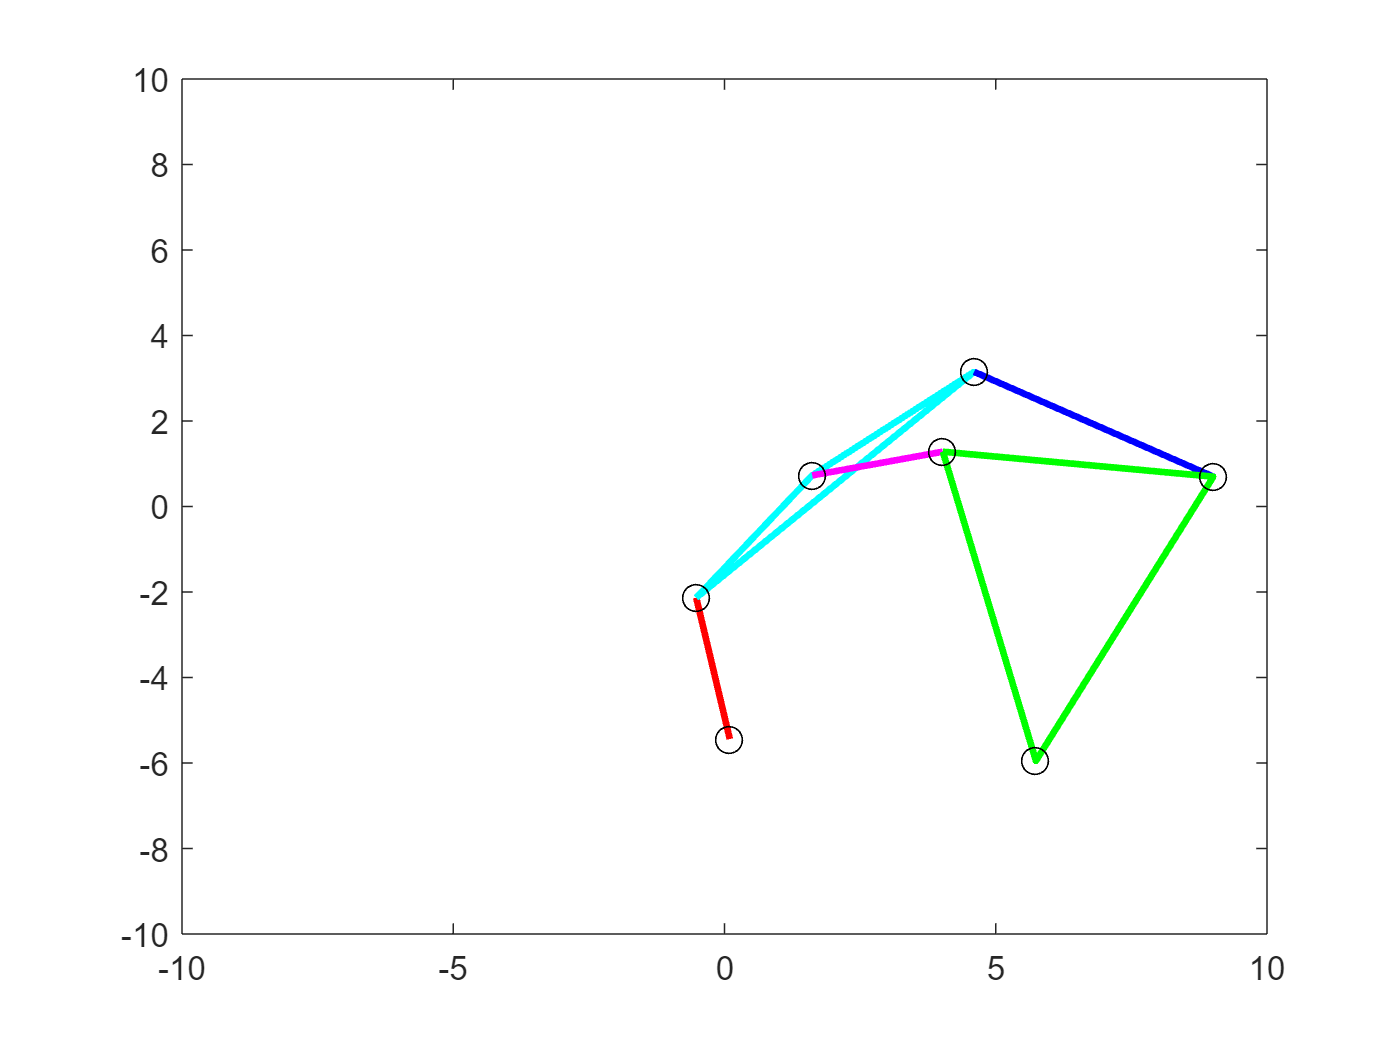

close all
clc

% Link lengths
L1 = link_lengths(1);
L2 = link_lengths(2); %coupler 1
L3 = link_lengths(3); %coupler 1
L4 = link_lengths(4); %coupler 1
L5 = link_lengths(5);
L6 = link_lengths(6);
L7 = link_lengths(7); %coupler 2
L8 = link_lengths(8); %coupler 2
L9 = link_lengths(9); %coupler 2

% Initial joint angles (in radians)
theta = angles;

% Time step for animation
tstep = 0.05;

    A = [0.098, -5.439];
    B = [-0.521, -2.134];
    C = [1.616, 0.727];
    D = [4.602, 3.150];
    E = [4.025, 1.282];
    F = [9.011, 0.698];
    G = [5.741, -5.950];

    % Plot the links and vertices
    figure(1)
    axis("equal")
    plot([A(1), B(1)], [A(2), B(2)], 'r', 'LineWidth', 2); hold on % link 1
    plot([B(1), C(1), D(1) B(1)], [B(2), C(2), D(2) B(2)], 'c', 'LineWidth', 2); % coupler link1
    plot([C(1), E(1)], [C(2), E(2)], 'm', 'LineWidth', 2); % link 3
    plot([D(1), F(1)], [D(2), F(2)], 'b', 'LineWidth', 2); % link 4
    plot([E(1), F(1), G(1), E(1)], [E(2), F(2), G(2), E(2)], 'g', 'LineWidth', 2); % coupler link
    plot(A(1), A(2), 'ko', 'MarkerSize', 8); % joint A
    plot(B(1), B(2), 'ko', 'MarkerSize', 8); % joint B
    plot(C(1), C(2), 'ko', 'MarkerSize', 8); % joint C
    plot(D(1), D(2), 'ko', 'MarkerSize', 8); % joint D
    plot(E(1), E(2), 'ko', 'MarkerSize', 8); % joint E
    plot(F(1), F(2), 'ko', 'MarkerSize', 8); % joint F
    plot(G(1), G(2), 'ko', 'MarkerSize', 8); % joint G
    ylim([-10 10])
    xlim([-10 10])